clc;
clear;
close all;
%% order selection
% add path to MATLAB
addpath('.\Urban Traffic Speed Dataset')
% load data
load roadhour.mat;
% road 117
road_example=roadhour(1:480,roadsample(2));
[xfreq, xpower]=fourier_transform(road_example);
% peak detection plot
findpeaks(xpower,xfreq,'MinPeakDistance',1/24,'MinPeakProminence',20000);% 'Annotate','extents','prominence', 'Threshold'
grid off
xline(xfreq(20),'--','HandleVisibility','off')
text(xfreq(31),12000000,['$\rightarrow f$=',num2str(xfreq(31))],'Interpreter','latex')
xline(xfreq(40),'--','HandleVisibility','off')
text(xfreq(62),6000000,['$\rightarrow f$=',num2str(xfreq(62))],'Interpreter','latex')
xline(xfreq(60),'--','HandleVisibility','off')
text(xfreq(93),4000000,['$\rightarrow f$=',num2str(xfreq(93))],'Interpreter','latex')
xline(xfreq(80),'--','HandleVisibility','off')
text(xfreq(124),2000000,['$\rightarrow f$=',num2str(xfreq(124))],'Interpreter','latex')
% peaks and location
[pks,locs]=findpeaks(xpower,xfreq,'MinPeakDistance',1/24,'MinPeakProminence',20000);
% maximum frequency = order * frequency
order=round(locs(end)*24);
fprintf('The optimal order of the %d-th road is %d.\n',roadindice(2),order)

The optimal order of the 117-th road is 4.


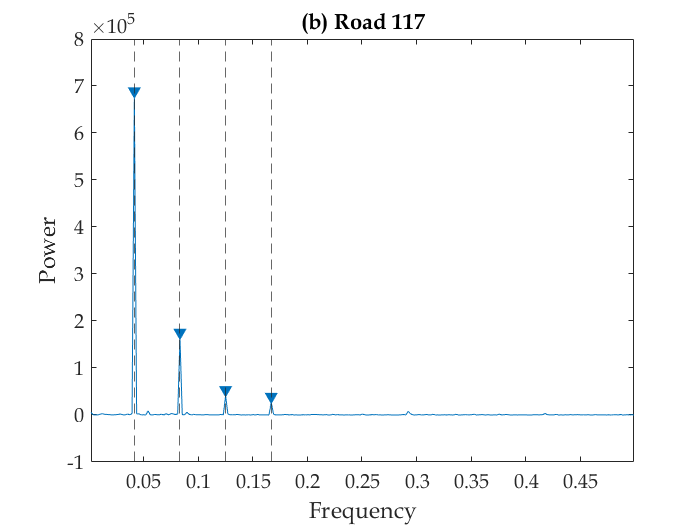

% plot(xfreq,xpower,'color',[0, 114, 189]/255,'LineWidth',1)
set(gca,'FontName','Book Antiqua','FontSize',12);
xlabel('Frequency','FontSize',14);
ylabel({'Power'},'FontSize',14);
tit={['(b) Road ',num2str(roadindice(2))]};
title(tit,'FontWeight','bold','FontSize',14);

% model setting
omega=pi/12; % angular frequency
gammamin=[1;1;1;1];
gammastep=[1;1;1;1];
gammamax=[20;20;20;20];
sigmamin=[1;1;1;1];
sigmastep=[5;5;5;5];
sigmamax=[100;100;100;100];
train=7*24;
test=24;
% figure setting
fig=figure('unit','centimeters','position',[5,5,40,20],'PaperPosition',[5, 5, 40,20],'PaperSize',[40,20]);
tit={['(a) Road ',num2str(roadindice(1))],['(b) Road ',num2str(roadindice(2))],['(c) Road ',num2str(roadindice(3))],['(d) Road ',num2str(roadindice(4))]};
tiledlayout(2,2,'TileSpacing','Compact','Padding','Compact'); % new subfigure
gamma=zeros(4,1);
sigma=zeros(4,1);
offline_data=[1:744]';
% begin loop
for l=1:4
    % the optimal order corresponding to road i
    orderi=order(l,1);
    % road i data from August 1 to August 31
    road_offline=roadhour(offline_data,roadsample(l));
    % meshgrid gamma and sigma
    gammainterval=[gammamin(l):gammastep(l):gammamax(l)]; % gamma
    sigmainterval=[sigmamin(l):sigmastep(l):sigmamax(l)];  % sigma
    [gammax,sigmay]=meshgrid(gammainterval,sigmainterval);
    [row,col]=size(gammax);
    road_test_all=[];
    road_pre_all=[];
    mae=zeros(row,col);
    % show calculating progress
    progress=waitbar(0,'Calculating, please wait!');
    for i=1:row
        for j=1:col
            k=1; % Mark the first position of the data to be calculated
            % String displayed by progress bar
            str=['Calculate progress: ',num2str(((i-1)*col+j)/(row*col)*100),'%'];
            % show progress bar
            waitbar(((i-1)*col+j)/(row*col),progress,str);
            % while the last used data less than the data length
            while (k+train+test-1)<=744
                % train data
                road_train=road_offline(k:k+train-1);
                % test data
                road_test=road_offline(k+train:k+train+test-1);
                % all test data
                road_test_all=[road_test_all;road_test];
                % call model code
                road_fit_pre = NGFM(road_train,omega,orderi,gammax(i,j),sigmay(i,j),test);
                % predictive data
                road_pre=road_fit_pre(train+1:end);
                % all predictive data
                road_pre_all=[road_pre_all;road_pre];
                % location update
                k=k+test;
            end
            mae(i,j)=mean(abs(road_pre_all-road_test_all));
        end
    end
    close(progress);
    nexttile % next subfigure
    % plot 3D surface
    mesh(gammax,sigmay,mae)
    set(gca,'FontName','Book Antiqua','FontSize',12);
    xlabel(['\gamma'],'FontSize',14);
    ylabel({'\sigma'},'FontSize',14);
    zlabel({'mean absolute error'},'FontSize',14);
    title(tit(l),'FontWeight','bold','FontSize',14);
    % minimal mae
    minmae=min(mae,[],'all');
    % row indice and column indice corresponding to minimal mae
    [minx,miny]=find(mae==minmae);
    % gamma optimization value
    gammaopt=gammax(minx,miny);
    fprintf('The optimal gamma of the %d-th road is %d.\n',roadindice(l),gammaopt)
    gamma(l,1)=gammaopt;
    % sigma optimization value
    sigmaopt=sigmay(minx,miny);
    fprintf('The optimal sigma of the %d-th road is %d.\n',roadindice(l),sigmaopt)
    sigma(l,1)=sigmaopt;
end
save('parameter.mat','gamma','sigma')

function [freq,power] = fourier_transform(x)
%% fast fourier transform function
y = fft(x); % fast fourier transform
y(1) = [];
n = length(y);
power = abs(y(1:floor(n/2))).^2; % power of first half of transform data
maxfreq = 1/2;                   % maximum frequency
freq = (1:n/2)/(n/2)*maxfreq;    % equally spaced frequency grid
end